**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Autors: P.Ozga & P.Pramod 

### dateset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

### Toolbox: Statistics and Machine Learning & Deep Learning

Clear bufor

close all; clear; clc

## Get the path to the dataset and show first 5 sample

fpath = fullfile(pwd, 'wine_quality_dataset.csv');%file path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');%correct read file
display(head(fname,5))% show first 5 samples - columns & rows

  5×12 table

    fixed acidity    volatile acidity    citric acid    residual sugar    chlorides    free sulfur dioxide    total sulfur dioxide    density     pH     sulphates    alcohol    quality
    _____________    ________________    ___________    ______________    _________    ___________________    ____________________    _______    ____    _________    _______    _______

         7.4                0.7                0             1.9            0.076              11                      34             0.9978  

% display(tail(fname,5)) % Show last 5 samples
% Check each column for non-numerical values
% for i = 1:width(fname)
%     column = fname{:, i}; % Extract the column data
%     if ~isnumeric(column) % Check if the column is not numeric
%         disp(['Column ' fname.Properties.VariableNames{i} ' has non-numerical values']);
%     end
% end

## Normalization all data

X = fname{:, 1:11};  % Features (first 11 columns)
Y = fname{:, 12};    % Quality rating (12th column)
X = (X - min(X)) ./ (max(X) - min(X));  % Min-Max normalization

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## Split the Data into Training and Test Sets:

### about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

cv = cvpartition(size(X, 1), 'HoldOut', 0.3);  %  extract the 70% trening, 30% test indices for cross-validation
% 
X_train = X(training(cv), :);
Y_train = Y(training(cv));
X_test = X(test(cv), :);
Y_test = Y(test(cv));

## Create and Train the MLP (Multilayer Perceptron) Network:

### about `feedforwardnet `function, link: https://ch.mathworks.com/help/deeplearning/ref/feedforwardnet.html

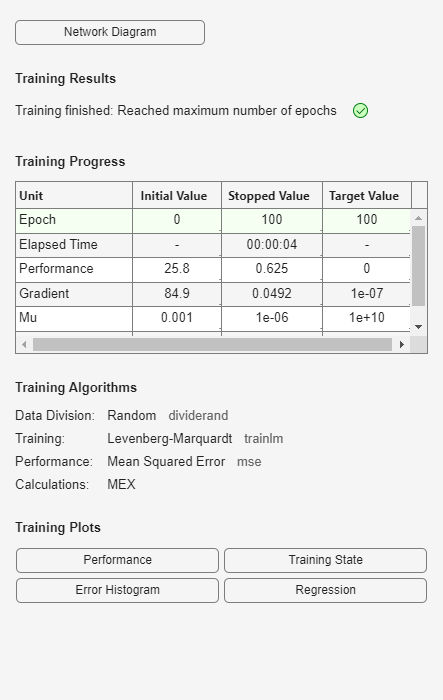

hiddenLayerSize = 12;           %number of neurons, number of feat
net = feedforwardnet(hiddenLayerSize);
net.trainFcn = 'trainlm';       % Levenberg-Marquardt training (+ Hesian information)
net.trainParam.epochs = 100;    % Number of epochs
net.trainParam.show = 50;       % Progress every 50 iterations

[net, tr] = train(net, X_train', Y_train');% Train the network

## Test the Network

net(X_test') % show vector

ans =     4.7458    4.9751    5.9238    5.7001    5.0248    4.5843    5.4049    4.1434    6.0189    5.9342    5.3702    6.1444    4.9821    5.8115    5.6267    4.7368    4.5302    4.7991    6.5856    6.5442    5.2398    5.1610    5.5460    5.1855    5.6508    5.6469    5.7147    5.5998    3.9494    4.4577    4.0006    5.8020    4.9047    5.5096    5.1633    4.8913    4.1491    4.6964    4.7316    4.0617    3.5544    3.8900    4.8312    2.4498    2.5917    6.1151    4.6491    5.2188    4.8235    4.5292


Y_pred = net(X_test');  % Predicting result
Y_pred = Y_pred';       % Transposing result
disp('True quality of wine:'); % from dataset

True quality of wine:


disp(Y_test);

     5
     5
     7
     6
     5
     5
     6
     6
     6
     5
     6
     5
     5
     5
     5
     5
     5
     5
     5
     6
     6
     4
     5
     5
     6
     5
     5
     5
     4
     6
     5
     6
     5
     5
     5
     6
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     5
     6
     6
     5
     5
     5
     5
     4
     5
     6
     5
     4
     5
     5
     5
     6
     5
     5
     5
     5
     5
     5
     7
     7
     5
     7
     6
     6
     5
     6
     6
     5
     7
     7
     5
     6
     5
     7
     6
     6
     6
     5
     5
     6
     8
     7
     7
     6
     5
     6
     5
     5
     6
     6
     6
     6
     5
     6
     5
     6
     6
     7
     7
     6
     6
     7
     6
     6
     6
     5
     5
     6
     5
     6
     6
     6
     6
     5
     7
     8
     5
     5
     6
     6
     6
     5
     5
     7
     6
     6
     6
     5
     6

disp('Predicting quality of wine:'); % from net

Predicting quality of wine:


disp(Y_pred);

    4.7458
    4.9751
    5.9238
    5.7001
    5.0248
    4.5843
    5.4049
    4.1434
    6.0189
    5.9342
    5.3702
    6.1444
    4.9821
    5.8115
    5.6267
    4.7368
    4.5302
    4.7991
    6.5856
    6.5442
    5.2398
    5.1610
    5.5460
    5.1855
    5.6508
    5.6469
    5.7147
    5.5998
    3.9494
    4.4577
    4.0006
    5.8020
    4.9047
    5.5096
    5.1633
    4.8913
    4.1491
    4.6964
    4.7316
    4.0617
    3.5544
    3.8900
    4.8312
    2.4498
    2.5917
    6.1151
    4.6491
    5.2188
    4.8235
    4.5292
    4.8730
    5.4494
    6.3299
    5.4054
    5.4054
    5.5209
    5.2295
    4.6829
    5.2650
    5.8304
    3.7241
    3.8217
    4.7570
    5.7238
    5.2625
    5.8136
    4.6728
    4.1337
    5.4489
    5.4489
    5.0728
    5.9697
    6.5291
    6.9499
    5.8328
    6.2871
    5.4944
    5.2204
    6.1682
    5.8402
    5.8979
    4.3493
    5.3992
    5.3992
    5.4572
    5.3814
    5.2359
    4.2912
    6.6234
    6.5960
    6.6234

mse = mean((Y_pred - Y_test).^2);
disp(['Mean square error (MSE): ', num2str(mse)]);

Mean square error (MSE): 0.73011


for classification it is better when you use metrics **accuracy**, **cross-entropy loss** or **F1-score**.

## Evaluate the Results

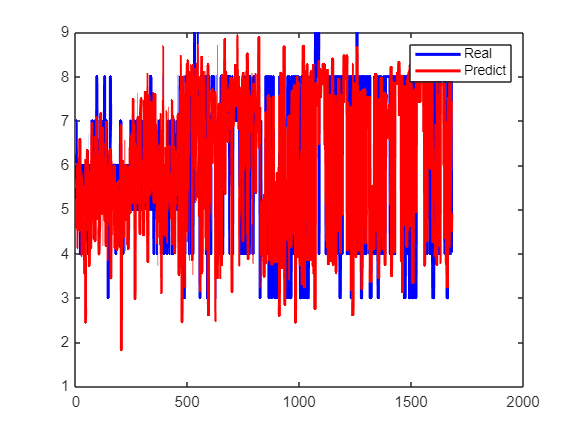

figure;                             % empty graph
plot(Y_test, 'b', 'LineWidth', 2);  % Real Value from dataset
hold on;                            % show the next graph on the same figure
plot(Y_pred, 'r', 'LineWidth', 2);  % Predicted Value from MLP
legend('Real', 'Predict');

% read about overfits, how to avoid and how to make overfits
%It helps to assess whether the model is learning well and whether there is overfitting.

### How to read histogram and different types of histogram in Polish :https://mfiles.pl/pl/index.php/Histogram